load('flow_data.mat')

## Part A.

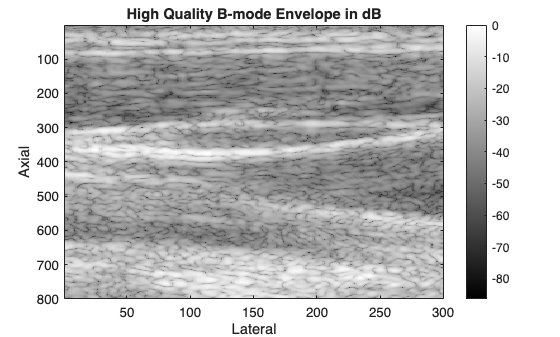

clf;

envh = abs(hilbert(rf_bmode));
envh_db = 20*log10(envh);
norm_envh = envh_db - max(envh_db(:));

figure()
imagesc(norm_envh);
colormap gray
colorbar;
title('High Quality B-mode Envelope in dB');
xlabel('Lateral');
ylabel('Axial');

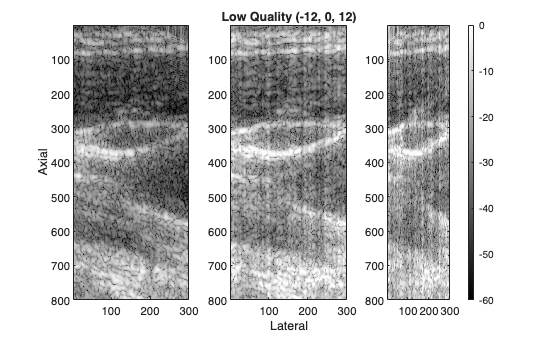


frame = 25;

envl1 = abs(hilbert(rf(:,:,frame,1)));
envl1_db = 20*log10(envl1);
norm_envl1 = envl1_db - max(envl1_db(:));

envl2 = abs(hilbert(rf(:,:,frame,2)));
envl2_db = 20*log10(envl2);
norm_envl2 = envl2_db - max(envl2_db);

envl3 = abs(hilbert(rf(:,:,frame,3)));
envl3_db = 20*log10(envl3);
norm_envl3 = envl3_db - max(envl3_db);

figure()
subplot(1,3,1)
imagesc(norm_envl1);
ylabel('Axial');
colormap gray;
clim([-60 0]);

subplot(1,3,2)
imagesc(norm_envl2);
title('Low Quality (-12, 0, 12)');
xlabel('Lateral');
colormap gray;
clim([-60 0]);

subplot(1,3,3)
imagesc(norm_envl3);
colormap gray;
colorbar;
clim([-60 0]);

## Part B. 

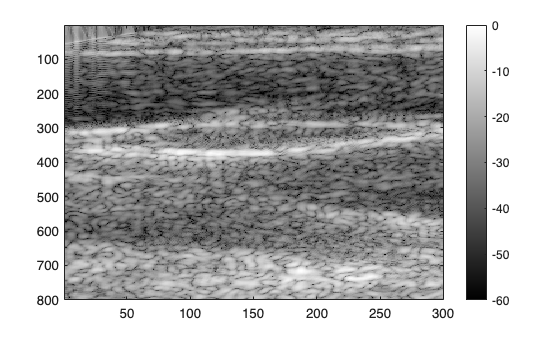

rf_12 = rf(:,:,:,3);

frames = 50;
M(frames) = struct('cdata', [], 'colormap', []);

vidfile = VideoWriter('b-mode.mp4','MPEG-4');
figure;
open(vidfile);
for i = 1:frames
    % Do we want/need to use hilbert transform here
    env = abs(hilbert(rf_12(:,:,i)));
    env_db = 20*log10(env);
    norm_env = env_db - max(env_db(:));
    
    imagesc(norm_env);
    colorbar;
    colormap gray;
    clim([-60 0]);

    drawnow;

    M(i) = getframe(gcf);
    writeVideo(vidfile, M(i));
end

close(vidfile);

## Part C.

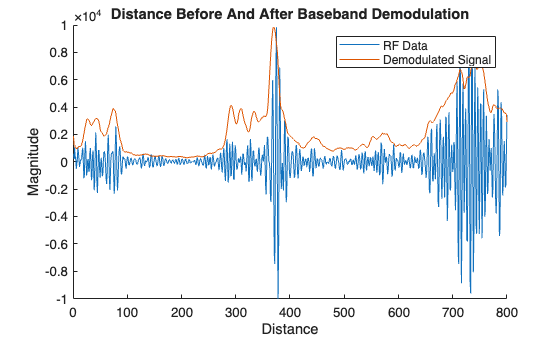

t = rf_12(1, 1, :);
d = (c / 2) * t;
q_demod = rf_12 .* exp(-2 * 1i * pi * f0 * d);
freq_spec = abs(hilbert(real(q_demod)));

freq_rf = abs(fft(rf_12));
freq_demod = abs(fft(demod_avg));

rf_avg = mean(rf_12, [2, 3]);
demod_avg = mean(freq_spec, [2, 3]);
demod_avg = demod_avg / max(demod_avg) .* max(rf_avg);

figure;
hold on;
plot(rf_avg);
plot(demod_avg);
legend(["RF Data", "Demodulated Signal"]);
title("Distance Before And After Baseband Demodulation");
% Add units
xlabel("Distance");
ylabel("Magnitude");
hold off;

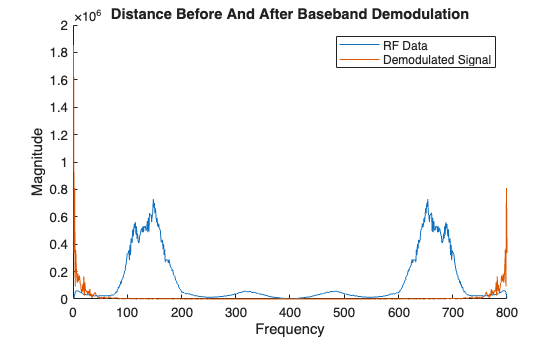

figure;
hold on;
plot(mean(freq_rf, [2, 3]));
plot(mean(freq_demod, [2, 3]));
legend(["RF Data", "Demodulated Signal"]);
title("Distance Before And After Baseband Demodulation");
% Add units
xlabel("Frequency");
ylabel("Magnitude");
hold off;

## Part D.

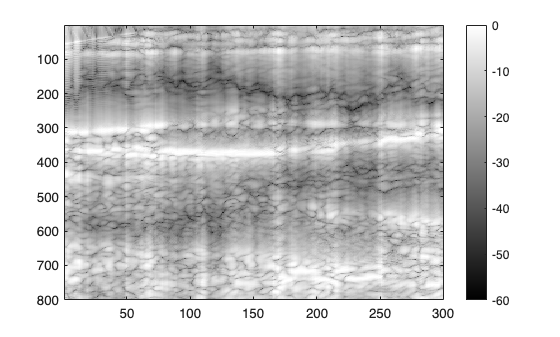

demod_double = double(freq_spec);
permute_data = permute(demod_double, [3 1 2]);

wf = wall_filter();
[b, a] = tf(wf);

filtered_permutated = filtfilt(b, a, permute_data);
filtered = permute(filtered_permutated, [2 3 1]);

envl_filtered = abs(hilbert(filtered(:,:,frame)));
envl_filtered_db = 20*log10(envl_filtered);
norm_envl_filtered = envl_filtered_db - max(envl_filtered_db);

imagesc(norm_envl_filtered);
colorbar;
colormap gray;
clim([-60 0]);

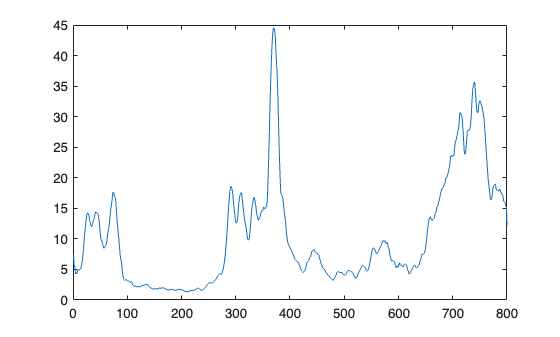

filtered_avg = mean(filtered, [2, 3]);
figure;
plot(filtered_avg);